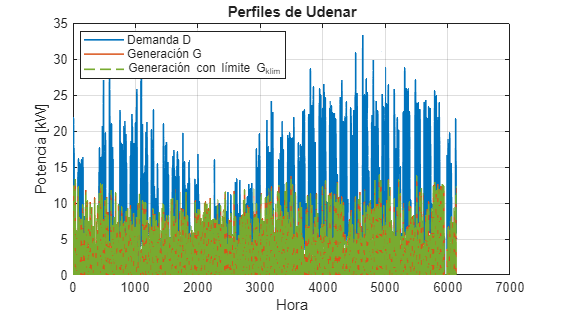

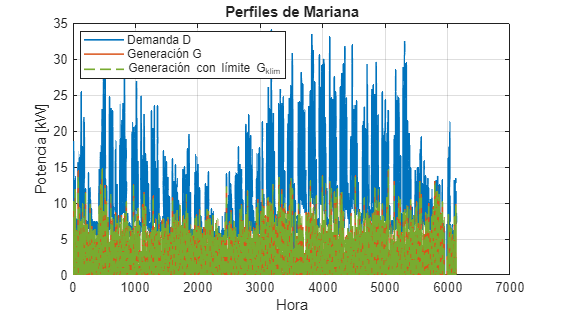

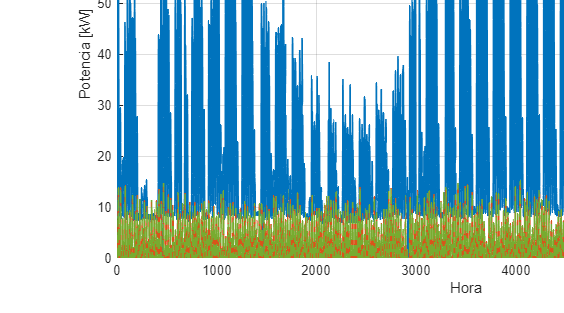

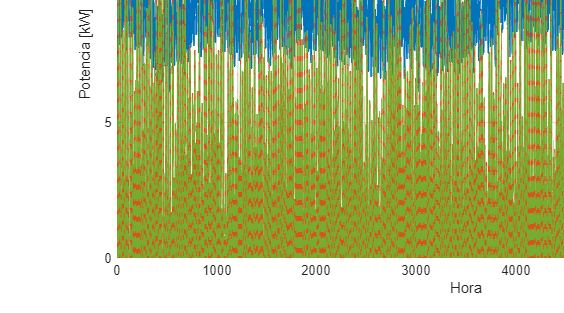

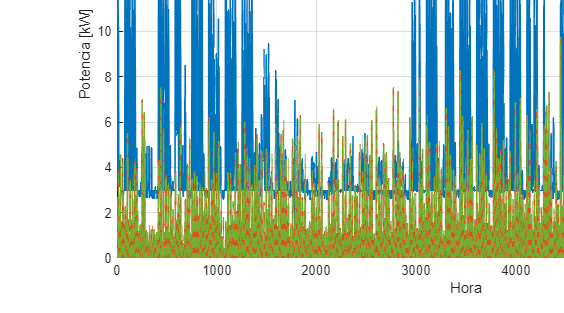

%% Cargar datos
S = load('fig1_perfiles.mat');

% Eje temporal (índice de muestra). Si el paso es 15 min, descomenta la 2da línea
t = double(S.hora(:));
% t = t * 0.25;   % para eje en horas

nodos = {'Udenar','Mariana','UCC','HUDN','Cesmag'};

%% Una figura por institución
for i = 1:numel(nodos)
    nodo = nodos{i};
    
    D     = S.(['D_'      nodo '_kW']);
    G     = S.(['G_'      nodo '_kW']);
    Gklim = S.(['Gklim_'  nodo '_kW']);
    
    figure('Color','w','Name',nodo,'Position',[100 100 900 500]);
    hold on; grid on; box on;
    
    plot(t, D(:),     'LineWidth', 1.2, 'Color', [0.00 0.45 0.74]);  % azul
    plot(t, G(:),     'LineWidth', 1.2, 'Color', [0.85 0.33 0.10]);  % rojo/naranja
    plot(t, Gklim(:), 'LineWidth', 1.2, 'Color', [0.47 0.67 0.19], ...
                      'LineStyle','--');                              % verde punteado
    
    xlabel('Hora');
    ylabel('Potencia [kW]');
    title(['Perfiles de ' nodo]);
    legend({'Demanda D','Generación G','Generación con límite G_{klim}'}, ...
           'Location','best');
    hold off;
end

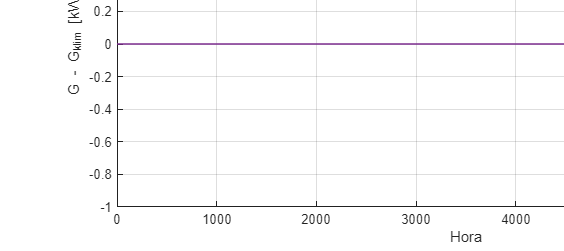


S = load('fig1_perfiles.mat');
t = double(S.hora(:));
nodos = {'Udenar','Mariana','UCC','HUDN','Cesmag'};

for i = 1:numel(nodos)
    nodo = nodos{i};
    
    G     = S.(['G_'     nodo '_kW'])(:);
    Gklim = S.(['Gklim_' nodo '_kW'])(:);
    dG    = G - Gklim;
    
    figure('Color','w','Name',['Diferencia ' nodo],'Position',[100 100 900 400]);
    plot(t, dG, 'LineWidth', 1.2, 'Color', [0.49 0.18 0.56]);
    grid on; box on;
    xlabel('Hora');
    ylabel('G - G_{klim} [kW]');
    title(['Diferencia G - G_{klim} — ' nodo]);
    
    % Estadísticas rápidas como texto en la gráfica
    txt = sprintf('máx: %.2f kW   media: %.2f kW   energía: %.2f kWh', ...
                  max(dG), mean(dG), sum(dG));   % ajusta el factor si t no es en h
    text(0.02, 0.95, txt, 'Units','normalized', ...
         'BackgroundColor','w','EdgeColor',[0.7 0.7 0.7]);
end